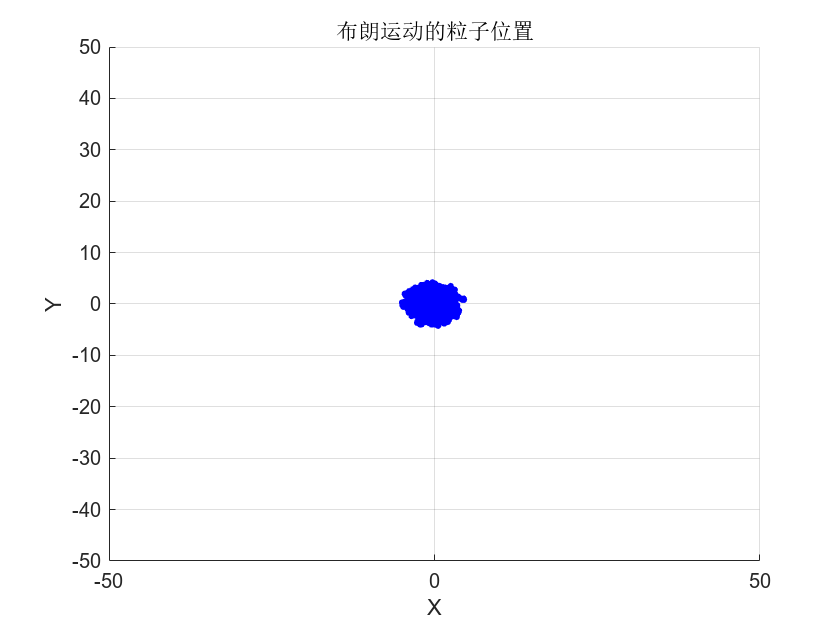

% 参数设置
num_particles = 1000; % 粒子数量
num_steps = 1000; % 时间步数
time_step = 0.01; % 时间步长
diffusion_coefficient = 1.0; % 扩散系数
damping_coefficient = 0.1; % 阻尼系数
collision_mean_free_path = 0.1; % 碰撞平均自由程

% 初始化粒子位置
x = zeros(num_particles, 1);
y = zeros(num_particles, 1);

% 用于存储粒子距离初始位置的平均平方位移随时间的变化
mean_squared_displacement = zeros(num_steps, 1);

% 创建图形窗口
figure;


% 模拟粒子运动
for step = 1:num_steps
    % 计算位移
    displacement_x = sqrt(2 * diffusion_coefficient * time_step) * randn(num_particles, 1) ...
                     - damping_coefficient * x * time_step ...
                     + collision_mean_free_path * randn(num_particles, 1);
                 
    displacement_y = sqrt(2 * diffusion_coefficient * time_step) * randn(num_particles, 1) ...
                     - damping_coefficient * y * time_step ...
                     + collision_mean_free_path * randn(num_particles, 1);
                 
    % 更新位置
    x = x + displacement_x;
    y = y + displacement_y;
    
    % 计算粒子距离初始位置的平方位移
    squared_displacement = (x.^2 + y.^2);
    
    % 计算平均平方位移
    mean_squared_displacement(step) = mean(squared_displacement);
    
    % 绘制粒子位置
    scatter(x, y, 10, 'b', 'filled'); % 每个粒子用蓝色点表示
    hold on;
    xlabel('X');
    ylabel('Y');
    title('布朗运动的粒子位置');
    axis([-50 50 -50 50]); % 设置坐标轴范围
    grid on;
    pause(0.01); % 暂停一小段时间，以便观察每个时间步的粒子位置
end

% 绘制粒子距离初始位置的平均平方位移随时间的变化
figure;
plot((1:num_steps)*time_step, mean_squared_displacement, 'b', 'LineWidth', 2);
hold on;
xlabel('时间');
ylabel('平均平方位移');
title('布朗运动的爱因斯坦方程');
grid on;

% 计算理论值
theoretical_value = 4 * diffusion_coefficient * (1:num_steps) * time_step;
plot((1:num_steps)*time_step, theoretical_value, 'r--', 'LineWidth', 2);
legend('模拟结果', '理论值');

% 显示图例和网格
legend('模拟结果', '理论值');
grid on;
